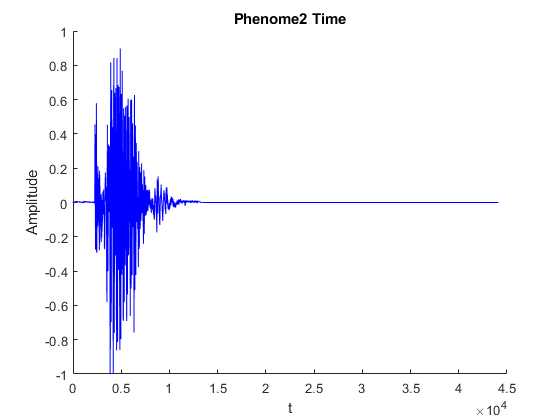

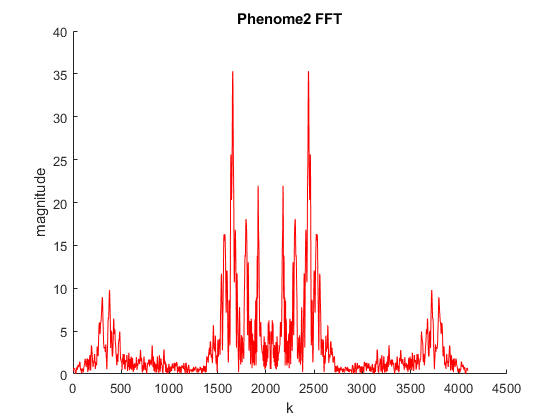

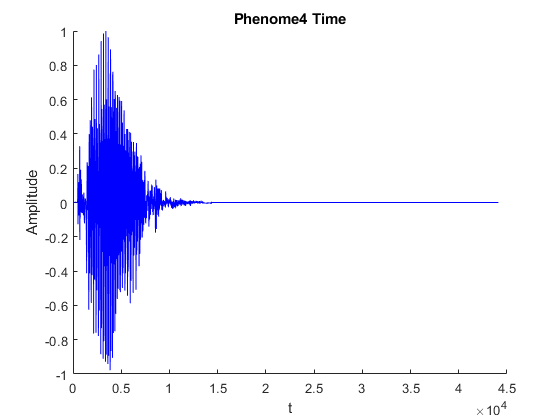

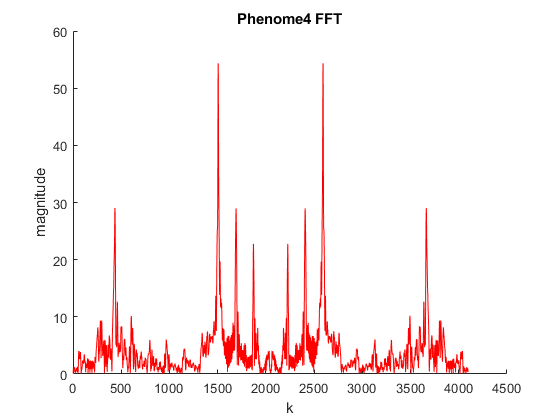

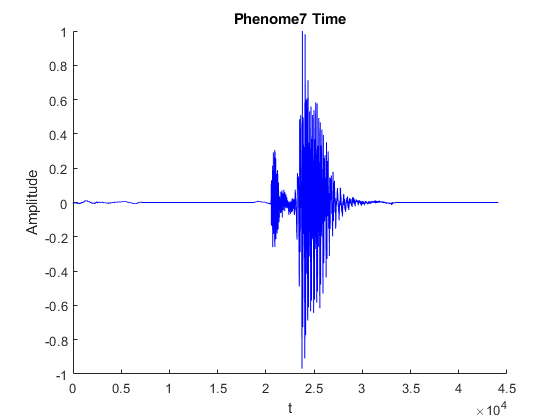

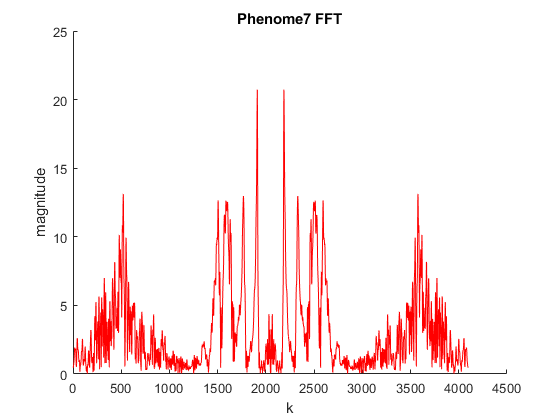

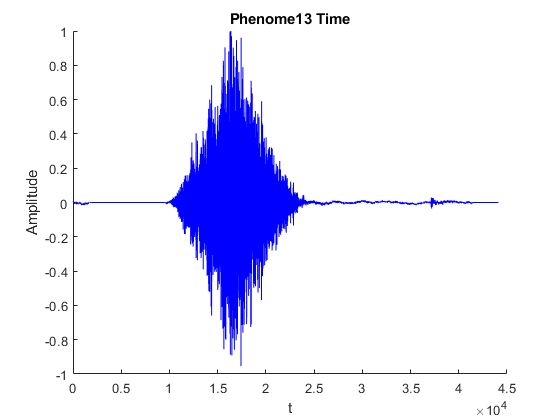

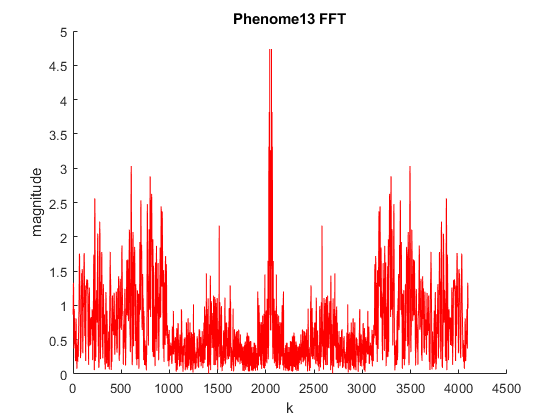

N = 2^12;
phenomes = MakePhenomes(N);

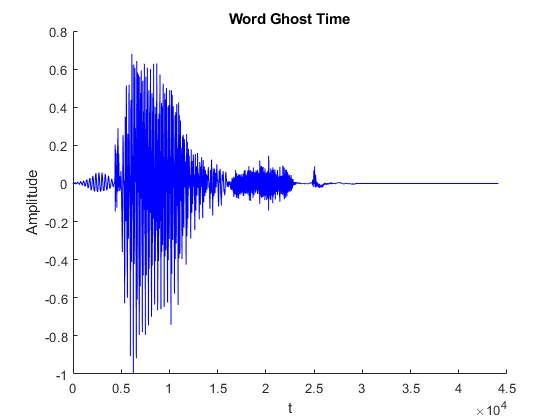

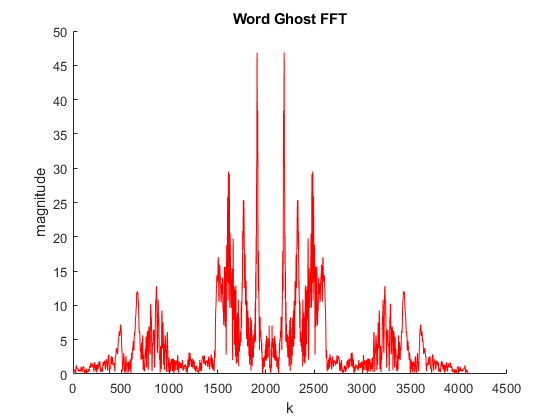

fileName = 'Words\Ghost.mp3';
[wordTime, wordFreq] = MakeWordFromSample("Ghost",fileName,N);

R1 = corrcoef(wordFreq,phenomes(1).FFT)

R1 =     1.0000    0.4549
    0.4549    1.0000


R2 = corrcoef(wordFreq,phenomes(4).FFT)

R2 =     1.0000   -0.1204
   -0.1204    1.0000


TimeData = {}


TimeData =

  0×0 empty cell array



FreqData = {}


FreqData =

  0×0 empty cell array



for i = 1:length(phenomes)
    TimeData{i} = xcorr(wordTime,phenomes(i).Time); 
    FreqData{i} = xcorr2(wordFreq,phenomes(i).FFT);
    E = sum(TimeData{i}.^2);
    disp("Energy " + phenomes(i).ID + " = " + E);
    %PlotTime(TimeData{i},phenomes(i).ID);
    %GraphFreq(FreqData{i},phenomes(i).ID);
    [P1,f1] = periodogram(wordTime,[],[],fs,'power');
    [P2,f2] = periodogram(phenomes(i).Time,[],[],fs,'power');/
end

Energy 2 = 6400305.4858
Energy 4 = 6756788.6735
Energy 7 = 6704767.3661
Energy 13 = 44432.958
Energy 14 = 84108.1277
Energy 25 = 1576350.7947
Energy 31 = 1290858.6235
Energy 32 = 8139293.3531


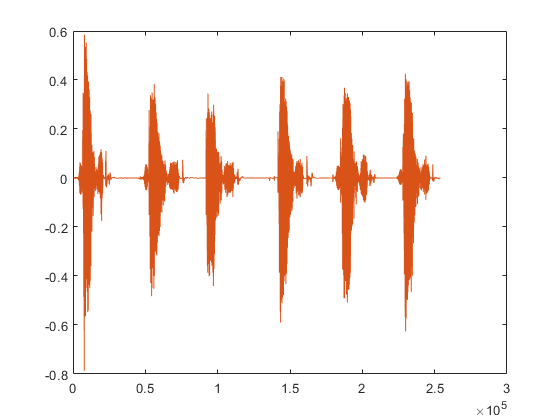



clf
[y, fs] = audioread(fileName);
duration = (length(y)-1)/fs;
plot(y)

sampleLength = fs;

[y1Combined] = preProcessor(fileName);
y1Len = length(y1Combined)

y1Len = 44100

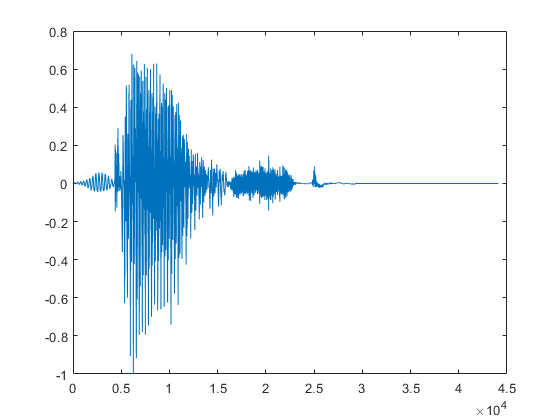


N = 2^12; %this is the N-parameter for the FFT. Out resolution, etc.
%============================
%    Sean:     We need a way to enfore a specific sample rate. Especially
%    since we resample. Not sure how we do that. Maybe since we know all
%    the samples come in with 44kHz, we can take a specific sample, because
%    a willy-nilly resample will change the meaning of the FFT indexes, so
%    for compatibility we need a standard.
%========

plot(y1Combined);

y1_resample = resample(y1Combined, N, y1Len);
y1RELen = length(y1_resample)

y1RELen = 4096

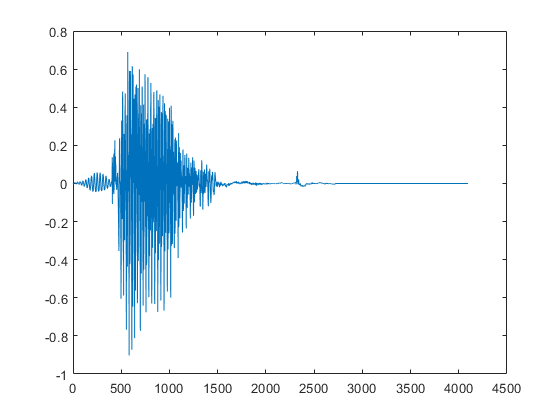

plot(y1_resample)

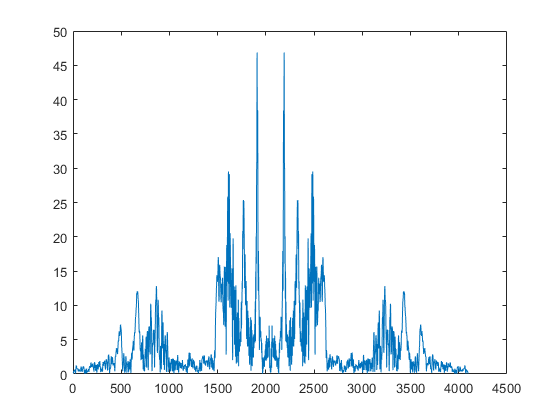

% sound(y1Norm,fs);
yFFT1 = abs(fftshift(fft(y1_resample)));
plot(yFFT1);

p2 = Phenome(2, yFFT1);

Not enough input arguments.

Error in Phenome (line 15)
            obj.Time = Time_;


%{
sampleSpot =2.92;
round(sampleSpot*fs)
y2 = y(round(lowerBound*fs + sampleSpot):round(upperBound*fs + sampleSpot),1);
[y2Norm] = normalizeAudio(y2);
y2_resample = resample(y2Norm, N, y1Len);
% sound(y2Norm,fs)
plot(y2Norm)
plot(y2_resample)
yFFT2 = abs(fftshift(fft(y2_resample)));

plot(yFFT2);
p2_2 = Phenome(2, yFFT2);

err = p2.GetSquareError(p2_2);
%}